# ** Optimizing Training Routines and Predicting Race times for Division 1 Distance Runners **

**Team:** Lu Han, Andrea Anez 

**Introduction:**

At the collegiate level there are four main distance running events in which athletes compete for conference and national titles: the 800m, the 1500m, the 5k, and the 10k. Although, at the olympic level the 800m and even the 1500m are considered a sprint, at the collegiate level most runners that compete in the 800m and up will also compete in cross country where they train alongside the 5k and 10k runners and thus have comparable, although not identical training routines. 

It is well known that training and lifestyle play a key role in determining how a distance runner will perform at the end of the season. However, to this day training regimens remain highly subjective and the actual impact of certain lifestyle choices are almost entirely anecdotal. We have created an interactive model that will help distance running coaches optimize training routines, lower race times and be able to better predict final performances.

To best understand which key metrics to analyze we spoke to Darius Terry, the head coach for Men’s and Women’s Cross Country at UCSB. According to Coach Terry, the metrics listed below are key factors in training regimens. However, he is unsure of the extent of the actual impact on race times. Note the order of these factors is arbitrary. 

Over a course of 10-12 weeks:

- Season Part (1 or 2)

- Iron intake (tablespoons / week)

- Ferritin levels (ng/ml)

- Running Volume (miles/ week)

- Sleep (hours/week) (EXCLUDED)

- Homeostasis score (1-10 scale / week) 

- Training consistency (total days off in the12 week time period)

- Recovery (average season score)

- Alcohol Intake (drinks/ week)

- Nutrition (1-10 score for entire season)(EXCLUDED)

- Year (years thus far in the program)

- A race time from the beginning of the season.

Factors Included from the week of a competition:

        13. Sleep 2 (average hours slept 1 and 2 days before)

        14. Homeostasis 2 (score for that week of competition)

We have created multiple mathematical models to predict the race times of athletes at the end of the season. Key attributes listed above are used as metrics to predict the time an athlete will run by the end of the season. From these models we can determine the attributes that are the most impactful to an athlete's final performance.

#### **Definition of Terms:**

*Conference*: The final 2 day competition between multiple schools where athletes will compete in their specialized events.Typically athletes will compete in more than one event. The athletes that run qualifying times will move on to regional competitions. 

*Season****:*** The 17-20 week training period before the final the Conference meet and or the National meet. 

*Personal Record (PR)*** :**The fastest time run by the athlete over the course of their racing career for a particular distance.

*MSE : *Mean Sqaured Error.

#### **Additional Information on Data Attributes:**

We have included additional information explaining the importance of each of the attributes we chose to include in our model. Additionally, we have listed the maximum and minimum values used to normalize the data between a 0-1 value. If a minimum value is not listed, it can be assumed the minimum value was 0. 


$$\textrm{data}\_\textrm{norm}=\frac{\left(\textrm{data}-\min \right)}{\max -\min }$$


**Season Part:**

Typically, the 10-12 weeks leading up to a competition are the most important. Generally, a season is 14-17 weeks long and athletes are typically expected to have their best race at the end of the season, this is known as “peaking”. However, athletes will sometimes have their best races at other points in the season. In order to capture this we take the best race time achieved at 70% through the season and at the end of the season (100%.) 10-12 weeks of training leading up to each  race in part 1 and part 2 of the season will be included in the model as a row of attributes. 

Season Part: 

Part 1: 0-70% of the season 

Part 2: 30 - 100% of the season

**Iron intake and Ferritin Levels:**

The value used for "Iron" was a seasonal average of mg of iron in liquid or pill form consumed daily. 

Maximum Value Used for Iron Intake: 70 mg of iron (average daily intake) 

Maximum Ferritin Level: 50 ng/dL

Foot strike hemolysis has long been known as a contributor to anemia in runners. When the foot strikes the ground blood cells are broken on impact. When running long distances over a long period of time this can cause many runners to develop anemia. In female long-distance runners foot strike hemolysis compounded with monthly menstruation causes an estimated 90% of female runners to be anemic or have low iron stores. Anemia in runners is a spectrum. The ideal Ferritin score for a long-distance runner is 50 ng/dL or greater, anything lower than a value of 30ng/dL is well known to compromise performance. Unfortunately, unless a runner shows symptoms of severe anemia or a blood test is administered it is difficult to determine if their iron stores are suboptimal. Experienced athletes on the UCSB cross country team typically take a daily iron supplement in order to optimize their race performance. However, most athletes do not take iron regularly and this likely has an impact on performance.

We decided to include both Iron and Ferritin as attributes since Iron intake doesn't necessarily lead to higher ferritin levels if the athlete is dosing incorrectly.

**Running Volume: **

Miles run per week is widely considered a key component of a distance running training program. It is the belief of many distance running coaches that progressively increasing the weekly mileage run by an athlete will increase their fitness and lower race times. 

When collecting data, we looked at the 12-14 weeks of training before a key race. The typical season is about 17-20 weeks in length. When calculating the average mileage for part 1 of the season we did not include the 3-4 weeks athletes spent “building” to their core mileage.  When calculating the average mileage for part 2 of the season we did not include the final week of the season where the athlete competed and ran low mileage. 

Women maximum mileage: 90 miles / week. 

Men maximum mileage:  100 miles / week. 

Minimum Value for both sexes is 20 miles / week. 

**Sleep:**

Adequate sleep is an essential means of recovery for distance runners. Typically, eight hours isn’t enough to allow the body to fully recover from a hard day of running especially when the athlete is doing upwards of 10 miles a day. Ideally collage runners should be getting 9-10 hours of sleep per night. 

Maximum Value: 10 hour /night 

Minimum Value: 5 hours.

**Homeostasis (Heath Score):**

In training logs filled out by the UCSB track and field there is a section where the athlete is required to put their “Homeostasis” value. A score of 10 would indicate fantastic health for that week while a score of 2 indicates that the athlete was very sick or injured.

Maximum Value: 10

Minimum Value: 2

**Training Consistency:**

Over the 10-12-week period we tallied all of the days that an athlete did not train. Although taking some rest days is essential to a well-balanced training plan, too many days off can lead to a reduction in fitness. 

Maximum Value:  20 days off per 12 weeks. 

**Recovery: **

In a questionnaire sent to all athletes included in the model we asked **them** to rate their weekly stretching routine. A score of 10 would indicate a thorough stretching routine completed daily and a 1 would indicate no stretching at all. 

Maximum Value: 10

**Alcohol Intake:** 

Alcohol is well known to have deleterious effects on athletic performance as well as recovery. Even minimal alcohol consumption can increase the risk of injury and put a strain on the heart. 

Although there were some outliers, we decided to set the maximum value at 12 drinks per average over the course of the training period.

Maximum Value: 12

**Nutrition:**

Athletes were asked to rate their nutritional intake for the season. Athletes that made time to eat three meals a day complete with fruit vegetables and a protein source were instructed to score themselves as a 10. Others that skipped meals or whose main calorie sources came from processed foods where instructed to score themselves less than 10 depending on the severity of these habits. 

Maximum Value: 10

**Years in the Program: **

The age of the athlete and more importantly the number of years they have run at the collegiate level is a key factor in determining their overall fitness. Typically, distance runners improve their times as they age however this is not the case for all athletes. 

Maximum Value: 5

Minimum Value: 1

**Previous Race Time:**

In order to give the model as much information as possible we included the race time of an earlier race. In order to keep data collection systematic, we used the best time ran during the first two races of the season and used this time for the athlete's Part 1 of that respective season. To calculate the previous race time for Part 2 of the season we used the best time ran in the last two races of Part 1. To normalize the race time, we used the equation seen below.


$$\textrm{norm}\;\textrm{race}\;\textrm{time}\;=\;\textrm{percent}\;\textrm{change}=\frac{\textrm{racetime}-\textrm{personal}\;\textrm{record}}{\textrm{personal}\;\textrm{record}}$$


**Data Sources:**

We will be obtaining our data from a survey sent out to the men’s and women’s cross-country teams as well as from weekly logs that are kept throughout the season. A sample of a typical log entry is shown below:

# 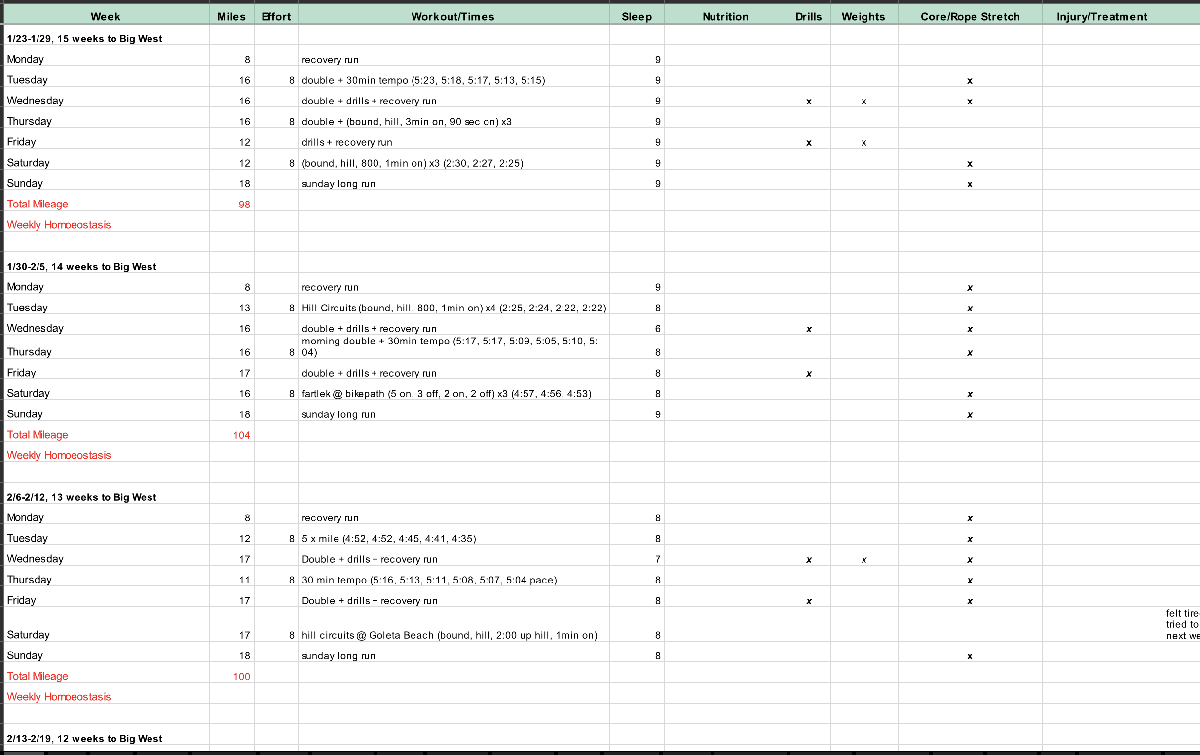

# Matlab Code:

## **Part 1: Data preprocessing + build model using CVX.**

% % female only
M = csvread('female.csv');
% % male only (enable line 4 to see the results of male)
 %M = csvread('male.csv');

n = size(M,1); % row
m = size(M,2) - 1; % column


**General Data Normalization:  **norm_val **= **  $\frac{\textrm{Current}\textrm{value}-\textrm{MIN}}{\textrm{MAX}-\textrm{MIN}}$


% general data normalization: MIN-MAX
for c = 1:m - 2
    minData = min(M(:,c));
    maxData = max(M(:,c));
    for r = 1:n
        M(r,c) = (M(r,c) - minData) / (maxData - minData); 
    end
end


#### **Data sets:**

We used two different classifiers for our data sets:

- Female

- Male 

We tested each classifier separately and as a group. When men’s and women's data are separated, we expect the model to become more accurate because the data becomes more homogeneous. Generally, men run faster than women and also respond to training differently. 

It should be noted that there were about half as many data points in the men’s data set as the women’s data set. This is due to the fact that women were far more reliable at entering training information into their logs.  

#### Y-Val Normalization Methods:

**Method 1 - normalize time as a 1-0 value:**


$$\textrm{norm}\;\textrm{race}\;\textrm{time}\;=\;\textrm{percent}\;\textrm{change}=\frac{\textrm{racetime}-\textrm{personal}\;\textrm{record}}{\textrm{personal}\;\textrm{record}}$$


 Each race time will then be represented as percent change from the fastest race time run by that athlete in that distance. This will allow us to capture improvement opposed to existing talent. It will also help us to compare between different distances and thus increase the size of our data set. 

    X_train_1 and X_test_1 contain the 14 attributes listed above. 

    In this method Y_train_1 and Y_test_1 are vectors representing the percentage of the difference between PR and race time over PR.

**Method 2 - Set Absolute Runtime as Y: **

Each race time is represented in seconds and this value was used as our y value. A new attribute was included that gave the distance run by the athlete for that particular time. Conceivably this model will give additional “spread” between each of the y values and increase the predictive power of the model.

X_train_2 and X_test_2 contain 13 attributes with one additional attribute; the distance of the race run in meters, "Distance(m)."

Y_train_2 and Y_test_2 are vectors representing the value of the race time in total seconds.

### **Models:**

**Model 1: Affine Linear Regressiom: **Y = a+Xw

Assume Y' and X' is testing data, a and w are variables

**Formula:** $\textrm{optimization}\;\textrm{formula}:$ $\min_{u\in R^n } \left\|Y-\left(a+\textrm{wX}\right)\right\|\underset{2}$ 

**Error: **$\textrm{mean}\;\textrm{sqaured}\;\textrm{error}={\left\|\left.y^{\prime } -\left(a+{\textrm{wX}}^{\prime } \right)\right)\right\|}_2$      $\textrm{where}\;y^{\prime } \;\textrm{is}\;\textrm{the}\;\textrm{the}\;\textrm{actual}\;y\;\textrm{value}\;\textrm{of}\;\textrm{the}\;\textrm{test}\;\textrm{data}\;\textrm{and}\;X^{\prime } \;\textrm{is}\;\textrm{the}\;x\;\textrm{values}\;\textrm{of}\;\textrm{the}\;\textrm{testing}\;\textrm{set}\ldotp$ 

**Model 2: Kernel Methods**

Observation: In many learning algorithms, 

– the weights can be written as a linear combo of sample points, & 

– we can use inner products of $\phi \left(x\right)$’s only --> don’t need to compute$\;\phi \left(x\right)$! The Kernel assosiated with the mapping of a $N\times N\;\textrm{Gram}\;\textrm{matrix}\;$is $k\left(x,z\right)={\phi \left(x\right)}^T \phi \left(z\right)$

Suppose w = $X^T$v = $\sum_{i=1}^n v_i X_i$ for some v$\epsilon \;R^n$.

Substitute this identity into alg. and optimize n dual weights a (aka dual parameters).

$\textrm{So},\;\textrm{assume}\;a\;\textrm{vector}\;v\;\textrm{with}\;\textrm{denominator}\;\textrm{of}\;\textrm{nx1},n\;\textrm{is}\;\textrm{the}\;\textrm{number}\;\textrm{of}\;\textrm{rows}\;\textrm{of}\;\textrm{training}\;\textrm{data}\;\ldotp \textrm{Using}\;\textrm{the}\;\textrm{equation}\;\textrm{from}\;\textrm{the}\;\textrm{linear}\;\textrm{method}\;\textrm{we}\;\textrm{will}\;\textrm{be}\;\textrm{replacing}\;\textrm{the}\;$$w$ with $X^T \times V$.

    $\textrm{Then}\;\underset{\min_{W\epsilon R^w } \left\|Y-\textrm{Xw}\right\|=\;\;\min_{V\epsilon R^2 } \left\|Y-X\times X^T \times V\right\|}$, $X\times X^T \;\textrm{forms}\;\textrm{an}\;N\times N\;\textrm{Gram}\;\textrm{matrix}\ldotp$ 

 **Quadratic Kernels**


$$\begin{array}{l}
\textrm{Starting}\;\textrm{from}\;\textrm{quadratic}\;\textrm{kernel},\;\textrm{when}\;\textrm{classifying}\;\textrm{with}\;\textrm{quadratic}\;\textrm{boundaries}\;\textrm{we}\;\;\textrm{use}\;\textrm{the}\;\textrm{following}\;\textrm{feature}\;\textrm{vectors}:\\
\;\phi \left(x\right)=\left(1,x_1 ,x_2 ,x_1^2 ,x_1 x_2 ,x_2^2 \right)
\end{array}$$



$$\textrm{Given}\;\textrm{two}\;\textrm{vectors}\;x,z\in R^2 ,\textrm{we}\;\textrm{have}:\;$$


 
$${\phi \left(x\right)}^T \phi \left(z\right)={\left(1+x^T z\right)}^2$$


**Polynomial Kernels**


$$\mathrm{Thus},\;\mathrm{more}\;\mathrm{generally}\;\mathrm{when}\;\phi \left(x\right)\;\mathrm{is}\;\mathrm{the}\;\mathrm{vector}\;\mathrm{formed}\;\mathrm{with}\;\mathrm{all}\;\mathrm{the}\;\mathrm{products}\;\mathrm{between}\;\mathrm{the}\;\mathrm{components}\;\mathrm{of}\;x\epsilon R^n ,\mathrm{up}\;\mathrm{to}\;\mathrm{degree}\;d,\mathrm{then}\;\mathrm{for}\;\mathrm{any}\;\mathrm{two}\;\mathrm{vectors}\;x,z\in R^n$$
 
$${\phi \left(x\right)}^T \phi \left(z\right)={\left(1+x^T z\right)}^d$$



$$\textrm{computational}\;\textrm{effort}\;\textrm{grows}\;\textrm{linearly}\;\textrm{in}\;n\;\textrm{opposed}\;\textrm{to}\;n^{d\;\;} \;\textrm{as}\;\textrm{seen}\;\textrm{in}\;\textrm{the}\;\textrm{brute}\;\textrm{force}\;\textrm{method}\ldotp$$


Based on the linear regression convex function, we can derive a new convex function from the procecies listed above by replacing the inner product with the kernel function:

    
$$\min_{V\epsilon R^N } {\left\|\left.Y-{\left(1+X\times X^T \right)}^d \times V\right)\right\|}_2$$


where the prediction for the testing data was calcualated by:

    
$$y^{\prime } =\phi \left(X^{\prime } \right)w\;=\phi \left(X^{\prime } \right)\times \phi X^T \times V$$
 

        
$$={\left(1+X^{\prime } \times X^T \right)}^d \times V$$


The mean sqaured error was calculated by:

     
$${\textrm{error}=\;\left\|y^{\prime } -{\left(1+X^{\prime } \times X^T \right)}^d \times V\right\|}_2$$


We randomly picked training datasets and generate each model for k times. Then we calculate the average mean square error for each model and print it out in the terminal. Here we first set k as 10 and use a cubic kernel. 

**We will be highlighting the models and subsequent data sets that were the most successful at predicting race times.**

% % female only
%M = csvread('female.csv');
% male only
 M = csvread('male.csv');

n = size(M,1); % row
m = size(M,2) - 1; % column


% general data normalization
for c = 1:m - 2
    minData = min(M(:,c));
    maxData = max(M(:,c));
    for r = 1:n
        M(r,c) = (M(r,c) - minData) / (maxData - minData); 
    end
end

cvx_setup


---------------------------------------------------------------------------
CVX: Software for Disciplined Convex Programming       (c)2014 CVX Research
Version 3.0beta, Build 1183 (dda2109)              Sun Dec 17 18:58:10 2017
---------------------------------------------------------------------------
Installation info:
    Path: /Users/andreaanez/Downloads/MATLAB/194 project/cvx
    MATLAB version: 9.8 (R2020a)
    OS: Mac OS X x86_64 version 10.14.6
    Java version: 1.8.0_202
Verfying CVX directory contents:
        /Users/andreaanez/Downloads/MATLAB/194 project/cvx/han_anez_final_notebook/ + 0 files, 0 subdirectories
        /Users/andreaanez/Downloads/MATLAB/194 project/cvx/running_data/ + 0 files, 0 subdirectories
        /Users/andreaanez/Downloads/MATLAB/194 project/cvx/female.csv
        /Users/andreaanez/Downloads/MATLAB/194 project/cvx/male.csv
        /Users/andreaanez/Downloads/MATLAB/194 project/cvx/project1


k = 30;
x = 0;

% MSE under different scnerios (comments are print out):
MSE_11 = 0;
MSE_12 = 0;
MSE_21 = 0;
MSE_22 = 0;
MSE_31 = 0;
MSE_32 = 0;
MSE_41 = 0;
MSE_42 = 0;

% sum1 and sum2 are sum of the weights for two linear regression models (print out below):
sum1 = zeros(12,1);
sum2 = zeros(13,1);

while k - x > 0
    
P = 0.60;
idx = randperm(n);

M_train = M(idx(1:round(P*n)),:);
M_test = M(idx(round(P*n)+1:end-1),:);
% Approach 1: Y as Percentage:

% Data Preprocessing
X_train_1 = M_train(:,1:m-3);
Y_train_1 = M_train(:,m);
X_test_1 = M_test(:,1:m-3);
Y_test_1 = M_test(:,m);

% Affline Linear Regression
cvx_begin
    variables a(1) b(size(X_train_1,2))
    minimize(norm(Y_train_1-(a(1)+X_train_1*b),2));
cvx_end

% Polynomial Kernel at n degree (PKn)
% Cubic Polynomial Kernel (PK3)
cvx_begin
    variables v(size(X_train_1,1))
    minimize(norm(Y_train_1-(1+X_train_1*transpose(X_train_1)).^3*v,2))
cvx_end


% Approach 2: Y as Absolute Runtime:

% Data Preprocessing
X_train_2 = M_train(:,1:m-2);
Y_train_2 = M_train(:,m-1);
X_test_2 = M_test(:,1:m-2);
Y_test_2 = M_test(:,m-1);

% Affline Linear Regression
cvx_begin
    variables c(1) d(size(X_train_2,2))
    minimize(norm(Y_train_2-(c(1)+X_train_2*d),2));
cvx_end

% Polynomial Kernel at n degree (PKn)
% Cubic Polynomial Kernel (PK3)
cvx_begin
    variables t(size(X_train_2,1))
    minimize(norm(Y_train_2-(1+X_train_2*transpose(X_train_2)).^3*t,2))
cvx_end

MSE_11 = MSE_11+ norm((Y_train_1-(a(1)+X_train_1*b)).* M_train(:,end),2);
MSE_12 = MSE_12+ norm((Y_test_1-(a(1)+X_test_1*b)).* M_test(:,end),2);

MSE_21 = MSE_21+ norm((Y_train_1-(1+X_train_1*transpose(X_train_1)).^3*v).* M_train(:,end),2);
MSE_22 = MSE_22+ norm((Y_test_1-(1+X_test_1*transpose(X_train_1)).^3*v).* M_test(:,end),2);

MSE_31 = MSE_31+ norm(Y_train_2-(c(1)+X_train_2*d),2);
MSE_32 = MSE_32+ norm(Y_test_2-(c(1)+X_test_2*d),2);

MSE_41 = MSE_41+ norm(Y_train_2-(1+X_train_2*transpose(X_train_2).^3*t),2);
MSE_42 = MSE_42+ norm(Y_test_2-(1+X_test_2*transpose(X_train_2).^3*t),2);

sum1 = sum1 + b;
sum2 = sum2 + d;
x = x + 1;
end

 
Calling SDPT3 4.0: 22 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 11
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|3.9e+00|6.1e+01| 5.000000e-01| 0:0:00|6.1e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|1.5e-01|3.5e-01|5.7e+00| 1.985083e-01| 0:0:00|3.2e+00|1.0e+00|8.9e-02| chol 1   1
 2|0.972|0.972|1.9e-02|5.0e-02|8.5e-01| 4.045416e-02| 0:0:00|3.7e-01|1

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|7.3e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|7.9e+00|4.3e-01|7.8e+00| 6.960407e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.972|0.972|4.3e-01|2.8e-02|3.4e-01| 7.139805e-03| 0:0:00|9.6e-02|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.3e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.623|0.623|1.2e+00|3.9e+00|8.7e+03| 4.706554e+02| 0:0:00|3.4e+03|7.5e-01|6.9e-01| chol 1   1
 2|0.799|0.799|8.6e-01|2.8e+00|8.6e+03| 7.513089e+02| 0:0:00|1.8e+03|5

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.037|0.037|1.4e+00|3.9e+00|5.2e+03| 7.315338e+02| 0:0:00|4.9e+03|9.9e-01|9.8e-01| chol 1   1
 2|0.156|0.156|1.3e+00|3.6e+00|4.9e+03| 6.727329e+02| 0:0:00|4.3e+03|

 
Calling SDPT3 4.0: 22 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 11
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+00|3.9e+00|6.1e+01| 5.000000e-01| 0:0:00|6.1e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.981|0.981|8.1e-02|2.6e-01|3.9e+00| 6.741805e-02| 0:0:00|2.3e+00|1.0e+00|6.8e-02| chol 1   1
 2|0.945|0.945|7.4e-03|2.9e-02|3.6e-01| 3.908728e-03| 0:0:00|1.3e-01|1

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.7e+01|4.3e-01|7.8e+00| 6.963529e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.971|0.971|9.5e-01|2.9e-02|3.4e-01| 7.893952e-03| 0:0:00|9.9e-02|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.1e+00|4.3e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.979|0.979|8.6e-01|3.4e+00|1.0e+04| 4.863822e+02| 0:0:00|2.4e+03|6.1e-01|4.8e-01| chol 1   1
 2|0.824|0.824|1.9e-01|7.4e-01|1.8e+03| 4.357160e+02| 0:0:00|2.2e+02|7

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.033|0.033|1.3e+00|3.9e+00|5.0e+03| 7.247910e+02| 0:0:00|5.0e+03|1.0e+00|9.9e-01| chol 1   1
 2|0.155|0.155|1.2e+00|3.5e+00|4.8e+03| 6.684081e+02| 0:0:00|4.3e+03|

 
Calling SDPT3 4.0: 22 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 11
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|6.1e+01| 5.000000e-01| 0:0:00|6.1e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|1.3e-01|4.0e-01|6.7e+00| 2.449402e-01| 0:0:00|3.8e+00|1.0e+00|1.0e-01| chol 1   1
 2|0.989|0.989|1.4e-02|4.6e-02|7.9e-01| 4.001691e-02| 0:0:00|3.2e-01|1

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.0e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.985|0.985|1.1e+01|4.3e-01|7.7e+00| 6.963875e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.970|0.970|6.3e-01|2.9e-02|3.5e-01| 8.619235e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+00|4.3e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.895|0.895|1.0e+00|3.7e+00|1.1e+04| 4.092663e+02| 0:0:00|2.6e+03|6.3e-01|5.4e-01| chol 1   1
 2|0.831|0.831|2.0e-01|7.2e-01|1.6e+03| 4.408417e+02| 0:0:00|1.9e+02|7

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.049|0.049|1.3e+00|3.9e+00|5.2e+03| 7.011590e+02| 0:0:00|4.9e+03|9.9e-01|9.8e-01| chol 1   1
 2|0.186|0.186|1.2e+00|3.6e+00|5.1e+03| 6.712775e+02| 0:0:00|4.2e+03|

 
Calling SDPT3 4.0: 22 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 11
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|6.1e+01| 5.000000e-01| 0:0:00|6.1e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.990|0.990|1.3e-01|3.8e-01|6.3e+00| 2.046225e-01| 0:0:00|3.8e+00|1.0e+00|9.8e-02| chol 1   1
 2|0.979|0.979|1.4e-02|4.6e-02|7.6e-01| 3.633848e-02| 0:0:00|3.1e-01|1

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.986|0.986|1.8e+01|4.3e-01|7.7e+00| 6.965937e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.970|0.970|9.9e-01|2.9e-02|3.5e-01| 8.722972e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+00|4.3e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.714|0.714|1.1e+00|3.9e+00|5.4e+03| 2.092610e+02| 0:0:00|1.8e+03|7.1e-01|6.5e-01| chol 1   1
 2|0.883|0.883|3.0e-01|1.0e+00|1.3e+03| 2.818095e+02| 0:0:00|3.2e+02|7

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.072|0.072|1.7e+00|3.8e+00|2.9e+03| 4.211303e+02| 0:0:00|2.8e+03|1.0e+00|9.7e-01| chol 1   1
 2|0.205|0.205|1.6e+00|3.6e+00|3.1e+03| 3.671067e+02| 0:0:00|2.5e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.1e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.8e-01|9.5e-01|2.1e+01| 7.411805e-01| 0:0:00|1.1e+01|8.9e-01|2.1e-01| chol 1   1
 2|0.988|0.988|4.9e-02|1.0e-01|2.2e+00| 9.451655e-02| 0:0:00|8.7e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|9.1e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.982|0.982|9.7e+00|4.2e-01|7.6e+00| 6.984276e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.967|0.967|5.7e-01|3.0e-02|3.6e-01| 1.061719e-02| 0:0:00|1.1e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.8e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.432|0.432|1.7e+00|4.3e+00|4.5e+03| 2.157897e+02| 0:0:00|2.2e+03|8.3e-01|8.1e-01| chol 1   1
 2|0.545|0.545|2.1e+00|3.4e+00|4.2e+03| 3.108248e+02| 0:0:00|2.1e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.9e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.100|0.100|2.0e+00|3.7e+00|2.9e+03| 4.038681e+02| 0:0:00|2.8e+03|1.0e+00|9.6e-01| chol 1   1
 2|0.290|0.290|1.7e+00|3.3e+00|2.8e+03| 3.410205e+02| 0:0:00|2.2e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.9e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|2.8e-01|6.0e-01|1.2e+01| 4.170668e-01| 0:0:00|6.7e+00|9.6e-01|1.4e-01| chol 1   1
 2|0.912|0.912|3.8e-02|8.7e-02|1.6e+00| 4.617564e-02| 0:0:00|8.0e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|7.6e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|8.2e+00|4.3e-01|7.8e+00| 6.971150e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.969|0.969|4.7e-01|3.0e-02|3.6e-01| 9.361193e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.510|0.510|1.3e+00|4.3e+00|8.2e+03| 4.344595e+02| 0:0:00|3.7e+03|7.9e-01|7.6e-01| chol 1   1
 2|0.702|0.702|1.5e+00|2.9e+00|6.4e+03| 4.658533e+02| 0:0:00|2.7e+03|7

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.050|0.050|1.4e+00|3.8e+00|5.0e+03| 7.336085e+02| 0:0:00|4.9e+03|1.0e+00|9.8e-01| chol 1   1
 2|0.151|0.151|1.3e+00|3.6e+00|5.0e+03| 6.473222e+02| 0:0:00|4.4e+03|

 
Calling SDPT3 4.0: 23 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|3.7e-01|6.8e-01|1.4e+01| 4.916825e-01| 0:0:00|7.8e+00|9.4e-01|1.6e-01| chol 1   1
 2|0.955|0.955|3.0e-02|6.0e-02|1.0e+00| 2.160828e-02| 0:0:00|4.4e-01|

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.1e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.2e+01|4.3e-01|7.8e+00| 6.960795e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.972|0.972|6.8e-01|2.9e-02|3.4e-01| 7.466762e-03| 0:0:00|9.7e-02|

 
Calling SDPT3 4.0: 24 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.519|0.519|1.2e+00|4.3e+00|8.3e+03| 4.661350e+02| 0:0:00|3.7e+03|7.8e-01|7.6e-01| chol 1   1
 2|0.733|0.733|1.2e+00|4.2e+00|1.4e+04| 6.896089e+02| 0:0:00|2.5e+03|

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.036|0.036|1.3e+00|3.9e+00|5.0e+03| 7.203506e+02| 0:0:00|4.9e+03|1.0e+00|9.9e-01| chol 1   1
 2|0.147|0.147|1.2e+00|3.6e+00|4.9e+03| 6.770295e+02| 0:0:00|4.4e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.1e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|5.8e-01|1.2e+00|2.7e+01| 9.317337e-01| 0:0:00|1.3e+01|8.6e-01|2.4e-01| chol 1   1
 2|1.000|1.000|6.0e-02|1.3e-01|3.0e+00| 1.485139e-01| 0:0:00|9.9e-01|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|8.4e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.986|0.986|9.0e+00|4.3e-01|7.7e+00| 6.962768e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.970|0.970|5.1e-01|2.9e-02|3.5e-01| 8.344994e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.538|0.538|1.2e+00|4.2e+00|8.2e+03| 4.603569e+02| 0:0:00|3.6e+03|7.8e-01|7.4e-01| chol 1   1
 2|0.753|0.753|1.2e+00|4.1e+00|1.4e+04| 6.874234e+02| 0:0:00|2.4e+03|5

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.046|0.046|1.3e+00|3.9e+00|5.2e+03| 7.310614e+02| 0:0:00|4.9e+03|9.8e-01|9.8e-01| chol 1   1
 2|0.154|0.154|1.2e+00|3.6e+00|5.1e+03| 6.678028e+02| 0:0:00|4.3e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.1e-01|1.2e+00|2.8e+01| 9.709865e-01| 0:0:00|1.4e+01|8.6e-01|2.5e-01| chol 1   1
 2|0.924|0.924|4.8e-02|1.4e-01|3.0e+00| 6.701738e-02| 0:0:00|1.3e+00|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|4.8e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.983|0.983|5.1e+00|4.2e-01|7.6e+00| 6.973431e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.967|0.967|3.0e-01|3.0e-02|3.6e-01| 1.048505e-02| 0:0:00|1.1e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.566|0.566|1.2e+00|4.2e+00|8.5e+03| 4.450916e+02| 0:0:00|3.5e+03|7.7e-01|7.3e-01| chol 1   1
 2|0.786|0.786|1.1e+00|4.0e+00|1.4e+04| 6.988286e+02| 0:0:00|2.2e+03|4

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.031|0.031|1.3e+00|3.9e+00|5.1e+03| 7.111416e+02| 0:0:00|4.9e+03|9.9e-01|9.9e-01| chol 1   1
 2|0.130|0.130|1.3e+00|3.8e+00|5.3e+03| 7.078131e+02| 0:0:00|4.5e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|3.9e-01|7.0e-01|1.4e+01| 5.054096e-01| 0:0:00|8.0e+00|9.4e-01|1.6e-01| chol 1   1
 2|0.957|0.957|3.0e-02|5.9e-02|1.0e+00| 1.724410e-02| 0:0:00|4.2e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.982|0.982|1.7e+01|4.2e-01|7.6e+00| 6.976222e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.968|0.968|9.8e-01|3.0e-02|3.5e-01| 1.010506e-02| 0:0:00|1.1e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.469|0.469|1.3e+00|4.3e+00|4.6e+03| 2.636195e+02| 0:0:00|2.2e+03|8.1e-01|7.8e-01| chol 1   1
 2|0.640|0.640|1.5e+00|3.1e+00|3.8e+03| 2.800766e+02| 0:0:00|1.7e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.091|0.091|1.6e+00|3.8e+00|2.9e+03| 3.874832e+02| 0:0:00|2.8e+03|1.0e+00|9.7e-01| chol 1   1
 2|0.301|0.301|1.4e+00|3.2e+00|2.7e+03| 3.346465e+02| 0:0:00|2.1e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.1e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.5e-01|9.1e-01|2.0e+01| 6.985804e-01| 0:0:00|1.0e+01|9.0e-01|2.0e-01| chol 1   1
 2|0.998|0.998|3.2e-02|6.9e-02|1.4e+00| 5.191219e-02| 0:0:00|4.5e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|3.0e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|3.2e+01|4.3e-01|7.8e+00| 6.960419e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.973|0.973|1.7e+00|2.8e-02|3.4e-01| 6.958512e-03| 0:0:00|9.6e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.595|0.595|1.2e+00|4.2e+00|8.6e+03| 4.423815e+02| 0:0:00|3.4e+03|7.6e-01|7.1e-01| chol 1   1
 2|0.794|0.794|1.1e+00|3.9e+00|1.4e+04| 6.688262e+02| 0:0:00|2.1e+03|4

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.5e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.035|0.035|1.5e+00|3.9e+00|5.0e+03| 7.261273e+02| 0:0:00|4.9e+03|1.0e+00|9.9e-01| chol 1   1
 2|0.139|0.139|1.4e+00|3.6e+00|4.9e+03| 6.766733e+02| 0:0:00|4.4e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.5e-01|8.1e-01|1.7e+01| 6.077495e-01| 0:0:00|9.3e+00|9.2e-01|1.8e-01| chol 1   1
 2|0.955|0.955|3.8e-02|7.4e-02|1.3e+00| 2.972019e-02| 0:0:00|5.7e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.0e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.1e+01|4.3e-01|7.8e+00| 6.961108e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.972|0.972|6.0e-01|2.8e-02|3.4e-01| 7.198261e-03| 0:0:00|9.6e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.477|0.477|1.3e+00|4.3e+00|4.6e+03| 2.632140e+02| 0:0:00|2.2e+03|8.0e-01|7.8e-01| chol 1   1
 2|0.646|0.646|1.5e+00|3.1e+00|3.8e+03| 2.776267e+02| 0:0:00|1.7e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.061|0.061|1.4e+00|3.9e+00|3.0e+03| 4.070271e+02| 0:0:00|2.8e+03|9.8e-01|9.8e-01| chol 1   1
 2|0.198|0.198|1.3e+00|3.7e+00|3.2e+03| 3.875808e+02| 0:0:00|2.5e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.3e-01|7.7e-01|1.6e+01| 5.754936e-01| 0:0:00|8.9e+00|9.2e-01|1.7e-01| chol 1   1
 2|0.969|0.969|3.6e-02|7.0e-02|1.3e+00| 3.960980e-02| 0:0:00|5.4e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.3e+01|4.3e-01|7.8e+00| 6.969757e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.970|0.970|7.1e-01|2.9e-02|3.5e-01| 8.899841e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.1e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.593|0.593|1.1e+00|4.1e+00|8.3e+03| 4.860543e+02| 0:0:00|3.4e+03|7.6e-01|7.1e-01| chol 1   1
 2|0.810|0.810|8.3e-01|3.2e+00|9.9e+03| 6.190149e+02| 0:0:00|1.9e+03|5

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.033|0.033|1.2e+00|3.9e+00|5.0e+03| 7.478665e+02| 0:0:00|5.0e+03|1.0e+00|9.9e-01| chol 1   1
 2|0.105|0.105|1.2e+00|3.8e+00|5.2e+03| 6.904242e+02| 0:0:00|4.6e+03|

 
Calling SDPT3 4.0: 22 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 11
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+00|3.9e+00|6.1e+01| 5.000000e-01| 0:0:00|6.1e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|1.3e-01|3.2e-01|5.1e+00| 1.729874e-01| 0:0:00|2.8e+00|1.0e+00|8.2e-02| chol 1   1
 2|0.913|0.913|1.7e-02|4.6e-02|6.5e-01| 1.595878e-02| 0:0:00|3.0e-01|1

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|4.3e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.986|0.986|4.7e+00|4.3e-01|7.7e+00| 6.972083e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.968|0.968|2.7e-01|3.0e-02|3.6e-01| 9.886018e-03| 0:0:00|1.1e-01|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.3e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.535|0.535|1.2e+00|4.0e+00|8.0e+03| 3.752594e+02| 0:0:00|3.5e+03|8.0e-01|7.5e-01| chol 1   1
 2|0.759|0.759|1.1e+00|3.7e+00|1.2e+04| 7.116260e+02| 0:0:00|2.3e+03|5

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.072|0.072|1.3e+00|3.9e+00|5.3e+03| 6.979082e+02| 0:0:00|4.8e+03|9.8e-01|9.7e-01| chol 1   1
 2|0.283|0.283|1.1e+00|3.2e+00|4.5e+03| 5.970769e+02| 0:0:00|3.6e+03|

 
Calling SDPT3 4.0: 22 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 11
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.5e+00|3.9e+00|6.1e+01| 5.000000e-01| 0:0:00|6.1e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.981|0.981|1.5e-01|4.1e-01|6.7e+00| 2.033922e-01| 0:0:00|4.3e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.982|0.982|1.7e-02|5.1e-02|8.6e-01| 4.214524e-02| 0:0:00|3.7e-01|1

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|6.3e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.984|0.984|6.8e+00|4.3e-01|7.7e+00| 6.967129e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.969|0.969|3.9e-01|2.9e-02|3.5e-01| 9.304813e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.5e+00|4.3e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.627|0.627|1.4e+00|3.9e+00|5.1e+03| 1.817387e+02| 0:0:00|1.9e+03|7.6e-01|7.0e-01| chol 1   1
 2|0.811|0.811|1.4e+00|3.8e+00|8.4e+03| 4.282121e+02| 0:0:00|1.2e+03|4

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.8e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.081|0.081|1.7e+00|3.9e+00|3.1e+03| 3.884110e+02| 0:0:00|2.8e+03|9.7e-01|9.7e-01| chol 1   1
 2|0.265|0.265|1.6e+00|3.5e+00|3.0e+03| 3.663633e+02| 0:0:00|2.3e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.2e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|6.0e-01|1.1e+00|2.6e+01| 9.041056e-01| 0:0:00|1.3e+01|8.7e-01|2.4e-01| chol 1   1
 2|1.000|1.000|7.2e-02|1.4e-01|3.4e+00| 1.774158e-01| 0:0:00|1.2e+00|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|9.3e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.985|0.985|9.9e+00|4.3e-01|7.7e+00| 6.961255e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.970|0.970|5.6e-01|2.9e-02|3.5e-01| 8.583218e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.454|0.454|1.6e+00|4.3e+00|4.5e+03| 2.244447e+02| 0:0:00|2.2e+03|8.2e-01|7.9e-01| chol 1   1
 2|0.592|0.592|1.9e+00|3.3e+00|4.0e+03| 2.615632e+02| 0:0:00|1.9e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.8e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.062|0.062|1.8e+00|3.9e+00|3.0e+03| 3.910512e+02| 0:0:00|2.8e+03|9.8e-01|9.8e-01| chol 1   1
 2|0.191|0.191|1.7e+00|3.7e+00|3.2e+03| 3.900417e+02| 0:0:00|2.5e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.5e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.7e-01|1.3e+00|3.1e+01| 1.064694e+00| 0:0:00|1.4e+01|8.4e-01|2.7e-01| chol 1   1
 2|0.906|0.906|6.7e-02|1.9e-01|4.1e+00| 8.720910e-02| 0:0:00|1.8e+00|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.0e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.1e+01|4.3e-01|7.8e+00| 6.967375e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.970|0.970|6.2e-01|2.9e-02|3.5e-01| 8.780358e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.545|0.545|1.2e+00|4.2e+00|8.4e+03| 4.542800e+02| 0:0:00|3.6e+03|7.7e-01|7.4e-01| chol 1   1
 2|0.769|0.769|1.2e+00|4.1e+00|1.4e+04| 7.076348e+02| 0:0:00|2.3e+03|5

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.040|0.040|1.3e+00|3.9e+00|5.2e+03| 7.175064e+02| 0:0:00|4.9e+03|9.9e-01|9.8e-01| chol 1   1
 2|0.143|0.143|1.2e+00|3.7e+00|5.2e+03| 6.826972e+02| 0:0:00|4.4e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|5.0e-01|9.0e-01|1.9e+01| 6.949121e-01| 0:0:00|1.0e+01|9.0e-01|2.0e-01| chol 1   1
 2|0.995|0.995|5.5e-02|1.0e-01|2.3e+00| 1.071938e-01| 0:0:00|8.9e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.0e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.985|0.985|2.2e+01|4.3e-01|7.7e+00| 6.961552e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.970|0.970|1.2e+00|2.9e-02|3.5e-01| 8.595727e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|2.9e+03| 4.270154e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.439|0.439|1.4e+00|4.3e+00|4.4e+03| 2.571230e+02| 0:0:00|2.2e+03|8.2e-01|8.0e-01| chol 1   1
 2|0.601|0.601|1.6e+00|3.2e+00|3.8e+03| 2.882588e+02| 0:0:00|1.8e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|2.9e+03| 4.270154e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.059|0.059|1.4e+00|3.9e+00|3.0e+03| 3.938041e+02| 0:0:00|2.8e+03|9.8e-01|9.8e-01| chol 1   1
 2|0.176|0.176|1.4e+00|3.8e+00|3.3e+03| 3.879894e+02| 0:0:00|2.5e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|6.1e-01|1.1e+00|2.5e+01| 8.772276e-01| 0:0:00|1.3e+01|8.7e-01|2.3e-01| chol 1   1
 2|1.000|1.000|6.5e-02|1.2e-01|2.9e+00| 1.368471e-01| 0:0:00|1.1e+00|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.4e+01|4.3e-01|7.8e+00| 6.959643e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.973|0.973|7.8e-01|2.8e-02|3.3e-01| 6.748930e-03| 0:0:00|9.5e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.469|0.469|1.5e+00|4.2e+00|4.5e+03| 2.266538e+02| 0:0:00|2.2e+03|8.2e-01|7.8e-01| chol 1   1
 2|0.553|0.553|1.9e+00|3.3e+00|4.1e+03| 2.725641e+02| 0:0:00|1.9e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.058|0.058|1.7e+00|3.9e+00|3.0e+03| 4.076922e+02| 0:0:00|2.8e+03|9.8e-01|9.8e-01| chol 1   1
 2|0.228|0.228|1.6e+00|3.5e+00|2.9e+03| 3.734431e+02| 0:0:00|2.3e+03|

 
Calling SDPT3 4.0: 22 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 11
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|4.6e+00|3.9e+00|6.1e+01| 5.000000e-01| 0:0:00|6.1e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|3.3e-01|2.8e-01|4.4e+00| 1.378899e-01| 0:0:00|2.3e+00|1.0e+00|7.2e-02| chol 1   1
 2|1.000|1.000|2.1e-02|2.3e-02|3.3e-01| 1.046491e-02| 0:0:00|9.0e-02|1

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.0e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.985|0.985|2.2e+01|4.3e-01|7.7e+00| 6.962062e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.971|0.971|1.2e+00|2.9e-02|3.4e-01| 8.107814e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.8e+00|9.2e+03| 7.512155e+02| 0:0:00|9.2e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.318|0.318|1.3e+00|4.1e+00|9.6e+03| 3.682870e+02| 0:0:00|7.8e+03|1.0e+00|8.6e-01| chol 1   1
 2|0.476|0.476|1.4e+00|4.6e+00|1.7e+04| 6.748151e+02| 0:0:00|6.7e+03|7

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.038|0.038|1.4e+00|3.9e+00|5.0e+03| 7.264582e+02| 0:0:00|4.9e+03|1.0e+00|9.8e-01| chol 1   1
 2|0.124|0.124|1.4e+00|3.7e+00|5.1e+03| 6.913121e+02| 0:0:00|4.5e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.6e-01|1.1e+00|2.5e+01| 8.896109e-01| 0:0:00|1.3e+01|8.7e-01|2.3e-01| chol 1   1
 2|0.964|0.964|4.5e-02|1.2e-01|2.5e+00| 6.795680e-02| 0:0:00|9.9e-01|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|6.7e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.986|0.986|7.2e+00|4.3e-01|7.7e+00| 6.962720e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.971|0.971|4.0e-01|2.9e-02|3.5e-01| 8.249797e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.549|0.549|1.2e+00|4.2e+00|8.4e+03| 4.631345e+02| 0:0:00|3.6e+03|7.7e-01|7.4e-01| chol 1   1
 2|0.767|0.767|1.1e+00|4.0e+00|1.4e+04| 6.779937e+02| 0:0:00|2.3e+03|5

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.3e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.056|0.056|1.3e+00|3.8e+00|5.0e+03| 7.105747e+02| 0:0:00|4.9e+03|1.0e+00|9.8e-01| chol 1   1
 2|0.209|0.209|1.1e+00|3.4e+00|4.7e+03| 6.318552e+02| 0:0:00|4.1e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|3.6e-01|8.7e-01|1.8e+01| 6.645145e-01| 0:0:00|1.0e+01|9.1e-01|1.9e-01| chol 1   1
 2|0.874|0.874|6.8e-02|1.7e-01|3.5e+00| 1.120504e-01| 0:0:00|1.7e+00|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.9e+01|4.3e-01|7.8e+00| 6.960293e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.973|0.973|1.0e+00|2.8e-02|3.4e-01| 6.941162e-03| 0:0:00|9.6e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|2.9e+03| 4.270154e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.499|0.499|1.4e+00|4.3e+00|4.7e+03| 2.532462e+02| 0:0:00|2.1e+03|7.9e-01|7.7e-01| chol 1   1
 2|0.691|0.691|1.5e+00|3.0e+00|3.7e+03| 2.845579e+02| 0:0:00|1.6e+03|7

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|3.9e+00|2.9e+03| 4.270154e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.062|0.062|1.7e+00|3.8e+00|2.9e+03| 3.989663e+02| 0:0:00|2.8e+03|1.0e+00|9.8e-01| chol 1   1
 2|0.228|0.228|1.5e+00|3.5e+00|2.8e+03| 3.639673e+02| 0:0:00|2.3e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.5e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.9e-01|1.4e+00|3.4e+01| 1.135760e+00| 0:0:00|1.5e+01|8.3e-01|2.8e-01| chol 1   1
 2|0.926|0.926|6.9e-02|1.9e-01|4.5e+00| 1.107759e-01| 0:0:00|1.8e+00|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.9e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|2.1e+01|4.3e-01|7.8e+00| 6.961996e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.971|0.971|1.1e+00|2.9e-02|3.4e-01| 7.861026e-03| 0:0:00|9.9e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|2.9e+03| 4.270154e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.511|0.511|1.4e+00|4.3e+00|4.8e+03| 2.449270e+02| 0:0:00|2.1e+03|7.9e-01|7.6e-01| chol 1   1
 2|0.733|0.733|1.5e+00|2.9e+00|3.7e+03| 2.809270e+02| 0:0:00|1.6e+03|7

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|3.9e+00|2.9e+03| 4.270154e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.060|0.060|1.7e+00|3.8e+00|2.9e+03| 4.022595e+02| 0:0:00|2.8e+03|1.0e+00|9.8e-01| chol 1   1
 2|0.201|0.201|1.6e+00|3.6e+00|2.9e+03| 3.638104e+02| 0:0:00|2.4e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.1e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|4.6e-01|8.9e-01|1.9e+01| 6.870805e-01| 0:0:00|1.0e+01|9.0e-01|2.0e-01| chol 1   1
 2|0.935|0.935|5.4e-02|1.1e-01|2.2e+00| 6.519500e-02| 0:0:00|1.0e+00|9

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.7e+01|4.3e-01|7.8e+00| 6.964555e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.971|0.971|9.6e-01|2.9e-02|3.5e-01| 8.165494e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.450|0.450|1.6e+00|4.3e+00|4.5e+03| 2.231948e+02| 0:0:00|2.2e+03|8.2e-01|7.9e-01| chol 1   1
 2|0.558|0.558|2.0e+00|3.3e+00|4.1e+03| 2.800789e+02| 0:0:00|2.0e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.9e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.073|0.073|1.9e+00|3.8e+00|2.9e+03| 4.140464e+02| 0:0:00|2.8e+03|1.0e+00|9.7e-01| chol 1   1
 2|0.222|0.222|1.8e+00|3.5e+00|2.9e+03| 3.462516e+02| 0:0:00|2.4e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.4e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|6.4e-01|1.1e+00|2.6e+01| 8.916452e-01| 0:0:00|1.3e+01|8.7e-01|2.4e-01| chol 1   1
 2|1.000|1.000|8.6e-02|1.5e-01|3.9e+00| 2.155032e-01| 0:0:00|1.3e+00|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|9.3e+01|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.0e+01|4.3e-01|7.8e+00| 6.959935e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.972|0.972|5.5e-01|2.8e-02|3.4e-01| 7.081021e-03| 0:0:00|9.6e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.454|0.454|1.3e+00|4.3e+00|4.5e+03| 2.630811e+02| 0:0:00|2.2e+03|8.1e-01|7.9e-01| chol 1   1
 2|0.617|0.617|1.5e+00|3.2e+00|3.8e+03| 2.802690e+02| 0:0:00|1.8e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.5e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.066|0.066|1.5e+00|3.8e+00|2.9e+03| 3.986402e+02| 0:0:00|2.8e+03|1.0e+00|9.7e-01| chol 1   1
 2|0.219|0.219|1.4e+00|3.5e+00|3.0e+03| 3.704618e+02| 0:0:00|2.4e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.3e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|6.2e-01|1.1e+00|2.6e+01| 9.069609e-01| 0:0:00|1.3e+01|8.7e-01|2.4e-01| chol 1   1
 2|1.000|1.000|7.4e-02|1.4e-01|3.4e+00| 1.744603e-01| 0:0:00|1.2e+00|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.3e+01|4.3e-01|7.8e+00| 6.960779e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.973|0.973|7.2e-01|2.8e-02|3.4e-01| 6.986865e-03| 0:0:00|9.6e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.2e+00|4.4e+00|1.4e+03| 2.039973e+02| 0:0:00|1.4e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.396|0.396|2.1e+00|4.2e+00|2.1e+03| 7.425085e+01| 0:0:00|1.1e+03|8.6e-01|8.3e-01| chol 1   1
 2|0.529|0.529|2.7e+00|3.4e+00|2.0e+03| 1.437459e+02| 0:0:00|1.1e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.1e+00|3.9e+00|1.4e+03| 2.039973e+02| 0:0:00|1.4e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.186|0.186|1.9e+00|3.5e+00|1.3e+03| 1.791793e+02| 0:0:00|1.2e+03|9.8e-01|8.8e-01| chol 1   1
 2|0.715|0.715|6.2e-01|1.1e+00|3.6e+02| 7.870139e+01| 0:0:00|2.2e+02|

 
Calling SDPT3 4.0: 23 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.9e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|3.7e-01|7.7e-01|1.6e+01| 5.793017e-01| 0:0:00|8.9e+00|9.2e-01|1.7e-01| chol 1   1
 2|0.898|0.898|6.1e-02|1.3e-01|2.6e+00| 8.760117e-02| 0:0:00|1.3e+00|

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.7e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|1.9e+01|4.3e-01|7.8e+00| 6.969783e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.971|0.971|1.1e+00|2.9e-02|3.5e-01| 8.228133e-03| 0:0:00|1.0e-01|

 
Calling SDPT3 4.0: 24 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.480|0.480|1.4e+00|4.3e+00|8.2e+03| 4.355068e+02| 0:0:00|3.8e+03|8.0e-01|7.8e-01| chol 1   1
 2|0.656|0.656|1.6e+00|3.1e+00|6.7e+03| 4.875535e+02| 0:0:00|3.0e+03|

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.4e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.035|0.035|1.4e+00|3.9e+00|5.0e+03| 7.324450e+02| 0:0:00|5.0e+03|1.0e+00|9.9e-01| chol 1   1
 2|0.121|0.121|1.3e+00|3.7e+00|5.1e+03| 6.842735e+02| 0:0:00|4.5e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.9e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|5.4e-01|1.2e+00|2.7e+01| 9.324653e-01| 0:0:00|1.3e+01|8.6e-01|2.4e-01| chol 1   1
 2|1.000|1.000|4.8e-02|1.1e-01|2.5e+00| 8.976064e-02| 0:0:00|8.7e-01|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.5e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.986|0.986|2.7e+01|4.3e-01|7.7e+00| 6.961408e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.972|0.972|1.5e+00|2.9e-02|3.4e-01| 7.673257e-03| 0:0:00|9.8e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+00|4.4e+00|5.1e+03| 7.512155e+02| 0:0:00|5.1e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.590|0.590|1.1e+00|4.2e+00|8.4e+03| 4.830818e+02| 0:0:00|3.5e+03|7.6e-01|7.1e-01| chol 1   1
 2|0.811|0.811|8.3e-01|3.2e+00|9.6e+03| 5.941321e+02| 0:0:00|1.8e+03|5

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.1e+00|3.9e+00|5.0e+03| 7.512155e+02| 0:0:00|5.0e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.035|0.035|1.1e+00|3.9e+00|5.0e+03| 7.256347e+02| 0:0:00|5.0e+03|1.0e+00|9.9e-01| chol 1   1
 2|0.186|0.186|9.8e-01|3.4e+00|4.4e+03| 6.430966e+02| 0:0:00|4.1e+03|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.4e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|6.6e-01|1.2e+00|2.7e+01| 9.263513e-01| 0:0:00|1.3e+01|8.6e-01|2.4e-01| chol 1   1
 2|1.000|1.000|6.6e-02|1.2e-01|2.8e+00| 1.227976e-01| 0:0:00|9.9e-01|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|3.1e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.987|0.987|3.3e+01|4.3e-01|7.8e+00| 6.961380e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.973|0.973|1.8e+00|2.8e-02|3.4e-01| 7.028848e-03| 0:0:00|9.6e-02|

 
Calling SDPT3 4.0: 23 variables, 8 equality constraints
------------------------------------------------------------

 num. of constraints =  8
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.4e+00|4.3e+00|7.1e+02| 9.636453e+01| 0:0:00|7.1e+02|1.0e+00|1.0e+00| chol 1   1
 1|0.533|0.533|2.1e+00|3.8e+00|1.0e+03|-3.079535e+00| 0:0:00|4.6e+02|8.5e-01|7.5e-01| chol 1   1
 2|0.825|0.825|3.4e+00|2.6e+00|9.2e+02| 8.561486e+01| 0:0:00|4.6e+02|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|3.2e+00|3.9e+00|1.4e+03| 2.039973e+02| 0:0:00|1.4e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.173|0.173|2.9e+00|3.6e+00|1.4e+03| 1.853549e+02| 0:0:00|1.2e+03|9.7e-01|9.0e-01| chol 1   1
 2|0.594|0.594|1.4e+00|1.7e+00|5.8e+02| 9.870418e+01| 0:0:00|4.5e+02|

 
Calling SDPT3 4.0: 23 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 12
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.2e+00|4.1e+00|6.8e+01| 5.000000e-01| 0:0:00|6.8e+01|1.0e+00|1.0e+00| chol 1   1
 1|1.000|1.000|5.5e-01|1.1e+00|2.4e+01| 8.327981e-01| 0:0:00|1.2e+01|8.8e-01|2.2e-01| chol 1   1
 2|1.000|1.000|6.5e-02|1.3e-01|3.1e+00| 1.680806e-01| 0:0:00|1.1e+00|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.2e+02|3.9e+00|6.7e+01| 1.658312e+00| 0:0:00|6.7e+01|1.0e+00|1.0e+00| chol 1   1
 1|0.986|0.986|1.3e+01|4.3e-01|7.7e+00| 6.961144e-01| 0:0:00|2.1e+00|1.0e+00|1.1e-01| chol 1   1
 2|0.972|0.972|7.2e-01|2.9e-02|3.4e-01| 7.585420e-03| 0:0:00|9.8e-02|

 
Calling SDPT3 4.0: 24 variables, 9 equality constraints
------------------------------------------------------------

 num. of constraints =  9
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 13
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.6e+00|4.4e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.485|0.485|1.6e+00|4.3e+00|4.7e+03| 2.229804e+02| 0:0:00|2.1e+03|8.1e-01|7.8e-01| chol 1   1
 2|0.638|0.638|1.9e+00|3.2e+00|4.0e+03| 2.582963e+02| 0:0:00|1.8e+03|8

 
Calling SDPT3 4.0: 21 variables, 10 equality constraints
------------------------------------------------------------

 num. of constraints = 10
 dim. of socp   var  = 11,   num. of socp blk  =  1
 dim. of free   var  = 10
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.8e+00|3.9e+00|2.9e+03| 4.295029e+02| 0:0:00|2.9e+03|1.0e+00|1.0e+00| chol 1   1
 1|0.072|0.072|1.8e+00|3.8e+00|2.9e+03| 4.045185e+02| 0:0:00|2.8e+03|1.0e+00|9.7e-01| chol 1   1
 2|0.204|0.204|1.7e+00|3.6e+00|3.1e+03| 3.761648e+02| 0:0:00|2.4e+03|

## **Part 2: MSE comparison for the two Y normalization methods and the two models**

Each model, linear regression and the kernel method, was tested on two methods: Y as percentage or as actual time. 

Y_test is the actual race time of the testing datasets. Y_linear_predict_1 is the predict race time use linear regression when Y is percentage. Y_kernel_predict_1 is the predict race time use kernel when Y is percentage. Y_linear_predict_2 is the predict race time use linear regression when Y is actual race time. Y_kernel_predict_2 is the predict race time use kernel when Y is actual race time.

Before we reached our optimal results, we tried 12-degree, 10-degree, and 5-degree Polynomial Kernel and Quadratic Kernel but finally found Cubic Kernel out performance the rest. We also excluded two factors: total sleep' and 'nutrition', as they appear to have no correlation.

Using male.csv, the following results are printed after 10 trials:

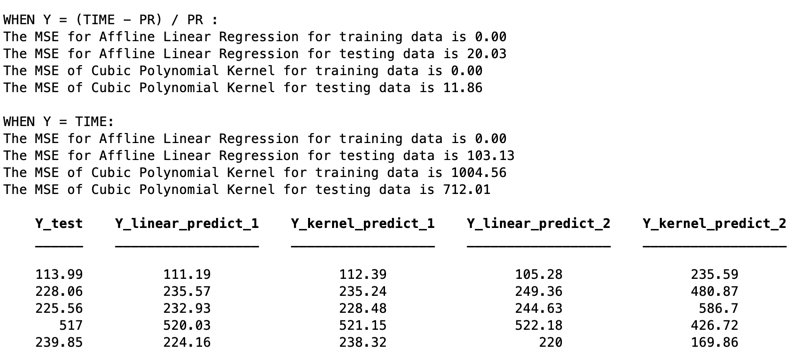

As we can see, with the same Y_test, the MSE for testing data when using Cubic Kernel and have y as percentage is the smallest. 

However, when using female.csv, the following results are printed after 10 trials:

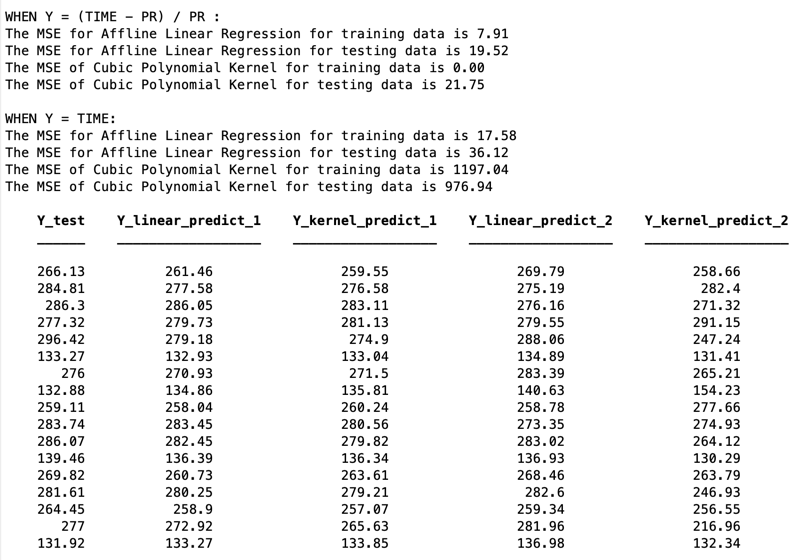

When Y is percentage, the difference between MSE for testing data and training data when using Linear Regression is smaller than that of Cubic Kernel with the MSE for training data as 0, which suggests that cubic kernel solver might be overfitting. It shows that the linear model can generalize better on testing data but cannot guarantee that it's a better model.

## Summary:

With the same Y-test, the overall MSE is smaller when y is represented as percentage of the PR. We multiplied the predicted percentage y with personal record then assed personal record to compare with the actual race time in the Y-test dataset. Thus, the variance of the prediction using total race time as y is larger than the variance when using a percentage of the race time as y. In other words, thus far we have seen that method 1 out preforms method 2 with our models.

After 500 trials on both dataset, overall speaking, the MSEs of cubic regression on training and testing dataset is smaller than those of linear regression. However, our cubic regression model definitely has overfitting issues compared to the linear regression model. The large MSE differences between training and testing dataset indicate that the model overfit to the training data and as a result cannot generalize to the testing data. 

### **Discussion about future improvements:**

#### Improvement for the overfitting of cubic regression:

To train with gradient descent might be better as CVX is always looking for a solution that could minimize the convex problem that generated by training data. By setting an adjustable minimum threshold for the convex problem instead of finding a minima, it's less likely to overfit the training data thus cannot generalize better on testing data.

#### Improvement for the datasets and MSE when y is actual runtime:

In the female.csv, after we take out some outliers, we only have 800m and 1500m in distances, which after MIN-MAX normalization, becomes 0s and 1s. While the function of normalization is to exaggerate the differences, 0s and 1s seems to be too polarized. More data points with run distance between 800m and 1500m would make the model to weight the 'distance' factor better, which might positively affect the MSE when y is actual runtime.



%Result1
fprintf('WHEN Y = (TIME - PR) / PR :\n');

WHEN Y = (TIME - PR) / PR :


fprintf('The MSE for Affline Linear Regression for training data is %.2f \n',MSE_11/k);

The MSE for Affline Linear Regression for training data is 0.00 


fprintf('The MSE for Affline Linear Regression for testing data is %.2f \n',MSE_12/k);

The MSE for Affline Linear Regression for testing data is 24.12 



fprintf('The MSE of Cubic Polynomial Kernel for training data is %.2f \n',MSE_21/k);

The MSE of Cubic Polynomial Kernel for training data is 0.00 


fprintf('The MSE of Cubic Polynomial Kernel for testing data is %.2f \n',MSE_22/k);

The MSE of Cubic Polynomial Kernel for testing data is 12.44 



Y_linear_predict_1 = (a(1)+X_test_1*b).* M_test(:,end)+M_test(:,end);

Y_kernel_predict_1 = (1+X_test_1*transpose(X_train_1)).^3*v.* M_test(:,end)+M_test(:,end);
% 
% 
%Result2
fprintf('\nWHEN Y = TIME:\n');


WHEN Y = TIME:


fprintf('The MSE for Affline Linear Regression for training data is %.2f \n',MSE_31/k);

The MSE for Affline Linear Regression for training data is 0.00 


fprintf('The MSE for Affline Linear Regression for testing data is %.2f \n',MSE_32/k);

The MSE for Affline Linear Regression for testing data is 57.94 



fprintf('The MSE of Cubic Polynomial Kernel for training data is %.2f \n',MSE_41/k);

The MSE of Cubic Polynomial Kernel for training data is 945.09 


fprintf('The MSE of Cubic Polynomial Kernel for testing data is %.2f \n\n',MSE_42/k);

The MSE of Cubic Polynomial Kernel for testing data is 782.40 




Y_linear_predict_2 = c(1)+X_test_2*d;

Y_kernel_predict_2 = (1+X_test_2*transpose(X_train_2)).^3*t;

Y_test = Y_test_2;

T2 = table (Y_test,Y_linear_predict_1,Y_kernel_predict_1,Y_linear_predict_2,Y_kernel_predict_2);
disp(T2);

    Y_test    Y_linear_predict_1    Y_kernel_predict_1    Y_linear_predict_2    Y_kernel_predict_2
    ______    __________________    __________________    __________________    __________________

    245.03          235.46                237.59                 228.8                60.486      
       905          887.24                892.82                895.78                504.69      
    234.39          241.51                242.03                235.65                36.952      
    113.58          112.33                113.26                 115.4                31.094      
    233.47          233.81                230.94                228.55                185.11      



## **Part 3: Weight (Most influential factors that affect runtime) - for linear regression model only:**

We didn't directly calculate the weight of cubic regression but instead used a kernel function to replace the inner product. Thus, we used the weights generated by linear regression model in both methods to decide which factors are comparatively more crucial to athlete's performance. There're 12 factors in the first method and 13 factors in second method. We printed out the tables including the all the sum of weights over the trial and the top 5 weights corresponding their variable names.

All the aforementioned factors except "alcohol" and including the additional factor for method 2, "Distance (m)", should have a negative weight, "b" or "d", if they are in fact correlated with faster race times. The larger the absolute value of the weight the more influential a factor is. For example, we expect that alcohol will have a positive weight because it should be correlated with slower race times. 

Each time the code is run the top five influential factors will shuffle slightly for each method. This is as expected since we have <45 rows of data for the women and <15 rows of data for the men and each time the rows of data are randomized the data of those particular athletes included in "x-train" will slightly skew the results. 

Additionally, we decided to exclude to data attributes, "sleep" and "nutrition" after testing for their weights and finding that they consistently had positive weights in both methods across both sexes. This would indicate that less sleep and eating poor would actually decrease race times. Although there are a number of factors at play here, the best, and most likely, explanation is that almost all athletes had weekly sleep averages well above 8 hours a week and similarly their average nutrition values over the course of a season where all roughly 8 out of 10. Because there was little deviation in the data when it came to these factors the factors essentially became arbitrary and where arbitrarily assigned a positive weight since most of the time an athlete will run slower than their PR.

In order to eliminate bias for each randomized round we summed up the weights over 30 trails. Then looked at the largest negative weights, and the largest absolute value of those negative weights compared to the absolute value of the weight of "alcohol."

Please note that the data from the men was collected over only a couple individuals and is probably less accurate than the women’s data. 

(In order of most to least influential)

**Top Influential Factors - Method 1:**

**Women:**

- Race Week Health Score 

- Alcohol Consumption (more alcohol predicted slower race times)

- Years in the Program (older athletes are predicted to perform better)

- Ferritin Level 

- Weekly Running Volume (higher mileage predicts faster race times)

- Race Week Sleep

**Men:**

- Season Part (athletes ran faster in the second half of the season)

- Weekly Running Volume (higher mileage predicts faster race times)

- Training Consistency

- Ferritin Level (not many boys had their ferritin checked so it could be inaccurate)

- Season Wide Health Score

 **Top Influential Factors- Method 2:**

**Women:**

- Race Distance (The longer the race the slower the time, we expected this)

- Weekly Running Volume (2 X more influential than all the other factors listed below)

- Training Consistency 

- Race Week Sleep

- Race Week Health Score

- Season Part (athletes ran faster in the second half of the season)

**Men: **

- Race Distance (The longer the race the slower the time, we expected this)

- Weekly Running Volume (higher mileage predicts faster race times)

- Iron Intake (note: not many boys had their ferritin levels checked, likely skewed by one athlete)

- Alcohol (more alcohol consumption was correlated with slower race times) 

- Season Wide Health Score 

- Race Week Sleep

**Summary:**

The major conclusion we can take from this data is that alcohol consumption is highly correlated with slower race times. Running volume as well as training consistency appears to benefit both sexes and be highly correlated with faster race times. Additionally, for women high ferritin levels are evidently very important.

Furthermore, the differences between the top influential factors for methods one and two in the women's data are an important point to highlight. When we look at the weight on alcohol for method two, we see that it is -234, this is a relatively large weight value, and it would typically indicate that the more alcohol an athlete was to drink the faster they would run. We know this is absurd for many reasons but most importantly it directly conflicts with our conclusions from method one where times were normalized by PR thus preventing “natural talent” from producing false positives. *From the results found in method one we can firmly conclude that greater alcohol consumption is highly correlated with running slower than your PR*. These findings, in addition to what can be found in the raw data, indicate that, for whatever reason, the fastest female athletes tend to drink the most alcohol and are negatively affected by it.

% variable names
var1 = ["season","iron intake (mg)","ferritin level","run volume","health score","training consistency","recovery","alchol","years in the program","2-days-before sleep","wo health score","Race before percent"];

fprintf('Most influencial X: \nY = (TIME - PR) / PR :\n');

Most influencial X: 
Y = (TIME - PR) / PR :


fprintf('All weights:\n');

All weights:


T = table(transpose(var1),sum1);
disp(T);

             Var1               sum1   
    ______________________    _________

    "season"                    -0.3403
    "iron intake (mg)"          0.58523
    "ferritin level"           -0.26439
    "run volume"               -0.43268
    "health score"             0.044205
    "training consistency"     -0.12498
    "recovery"                   0.1095
    "alchol"                   -0.15729
    "years in the program"    -0.072461
    "2-days-before sleep"     -0.014549
    "wo health score"           0.62802
    "Race before percent"       0.61728



[M,I] = maxk(abs(sum1),5);
Name = transpose(var1(I));
T = table(M,I,Name);
fprintf('\nTop 5 factors with max absolute weights:\n');


Top 5 factors with max absolute weights:


disp(T);

       M       I             Name         
    _______    __    _____________________

    0.62802    11    "wo health score"    
    0.61728    12    "Race before percent"
    0.58523     2    "iron intake (mg)"   
    0.43268     4    "run volume"         
     0.3403     1    "season"             




var2 = ["season","iron intake (mg)","ferritin level","run volume","health score","training consistency","recovery","alchol","years in the program","2-days-before sleep","wo health score","Race before percent","Distance(m)"];

fprintf('\nY = TIME:\n');


Y = TIME:


fprintf('All weights:\n');

All weights:


T = table(transpose(var2),sum2);
disp(T);

             Var1              sum2  
    ______________________    _______

    "season"                  -121.61
    "iron intake (mg)"         -3.301
    "ferritin level"           348.51
    "run volume"              -173.74
    "health score"             63.853
    "training consistency"     40.996
    "recovery"                 48.688
    "alchol"                   227.81
    "years in the program"     132.15
    "2-days-before sleep"     -82.911
    "wo health score"          270.81
    "Race before percent"      39.464
    "Distance(m)"               23345



[M,I] = maxk(abs(sum2),5);
Name = transpose(var2(I));
T = table(M,I,Name);
fprintf('\nTop 5 factors with max absolute weights:\n');


Top 5 factors with max absolute weights:


disp(T);

      M       I           Name       
    ______    __    _________________

     23345    13    "Distance(m)"    
    348.51     3    "ferritin level" 
    270.81    11    "wo health score"
    227.81     8    "alchol"         
    173.74     4    "run volume"     



## **Conclusion:**

It should be first noted that there are limitations to what we can conclude based on this data set due to a number of factors. First, running logs are self reported, and although most athletes anonymously reported that they were not dishonest in their training logs, the data could be, for a variety of reasons, slightly inaccurate. Additionally, it is worth noting that athletes who became injured due to over training or incidental reasons were not included because they did not have race times. This is particularly important because we have concluded that increased weekly running volume is predictive of faster times, however, there is an unweighted cost of those athletes which become injured running higher mileage. Lastly, at certain points when athletes forgot to put their sleep for a week or only had partial ferritin level records, one of the authors, Andrea, a runner on the team herself, filled in with the most accurate numerical value she could come up with based on written data and her knowledge of the athlete. If an athlete was missing too much data they where excluded from the study all together.

Overall, we have found that it is possible to predict the men’s time within average margin of three seconds and a mode of one second error using the kernel method and data from method one, this was the best performing combination of methods for the men’s data. It is possible that the kernel method worked best for the men’s data because it was more homogenous and over fitting wasn’t as much of a concern.

For the women’s data the linear regression model performed the best over all. The average predicted time was off from the actual time by an average of five seconds with a mode of one second and an outlier of sixteen seconds. What we where noticing looking at the results is that the model would predicts many times within a second but then be off by a large margin in others.

The accuracy of the model changes slightly with each test 

Although, a varity of distances where included in this model the most common distance used was a 1500m. A four-three second adverage prediction accuracy is not out of range with what a coach could predict.

We hope that our findings help coaches better predict race times and conference placings. Additionally we hope that through this report coaches can see empirically how athletes' choices on and off the track directly impact race times.